# Create and Customize Polar Scatter Plots

`polarplot` plots a line in polar coordinates defined by a set of angles versus a set of radii. The angle and radius inputs must be vectors of the same length where the angle is specified in radians.

### Create Angle and Radius Vectors

Define an evenly spaced angle vector that spans an entire circle. Create a rho vector as a function of the angle.

theta = 0:0.01:2*pi;
rho = sin(2*theta).*cos(2*theta);

### Basic Polar Plot

Plot the two vectors to form the spiral pattern as the value of each radius increases with theta.

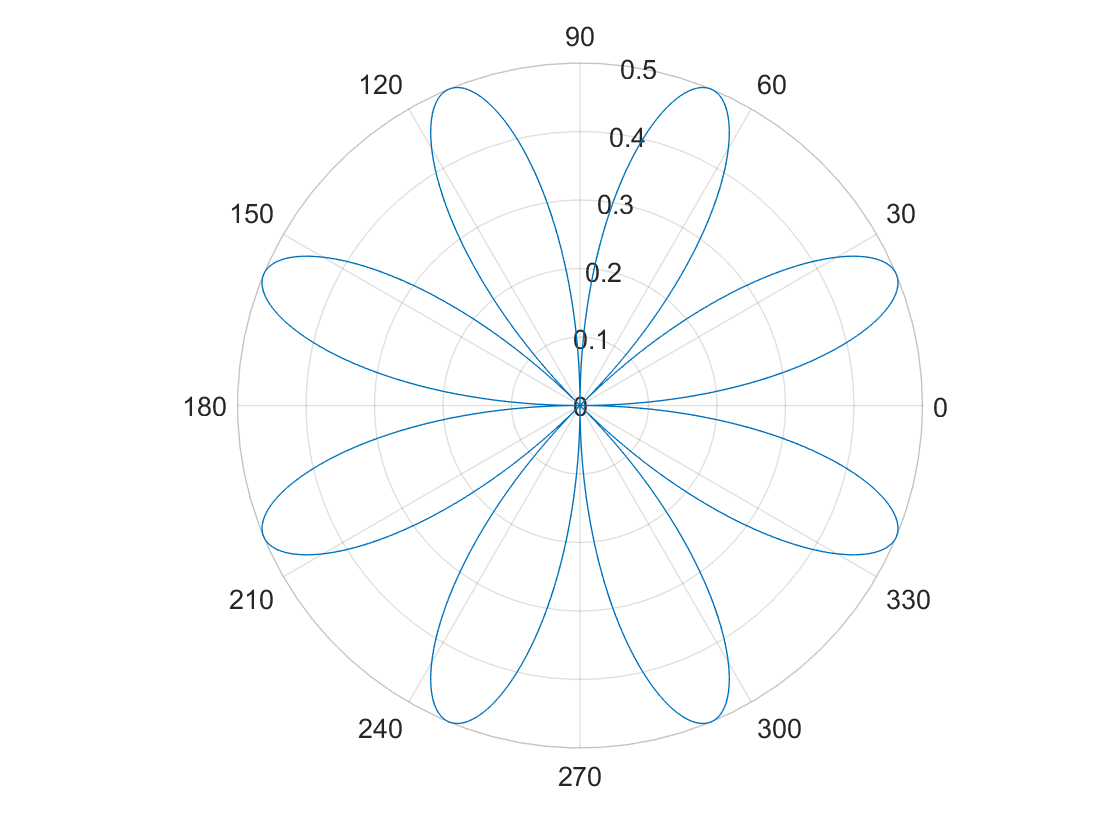

polarplot(theta,rho)

## Customizations

### Create a Complex Polar Plot

A polar plot can be used to visualization of compex values in polar coordinates. Providing a vector of complex numbers to polar plot along with a point type will display markers at each point.

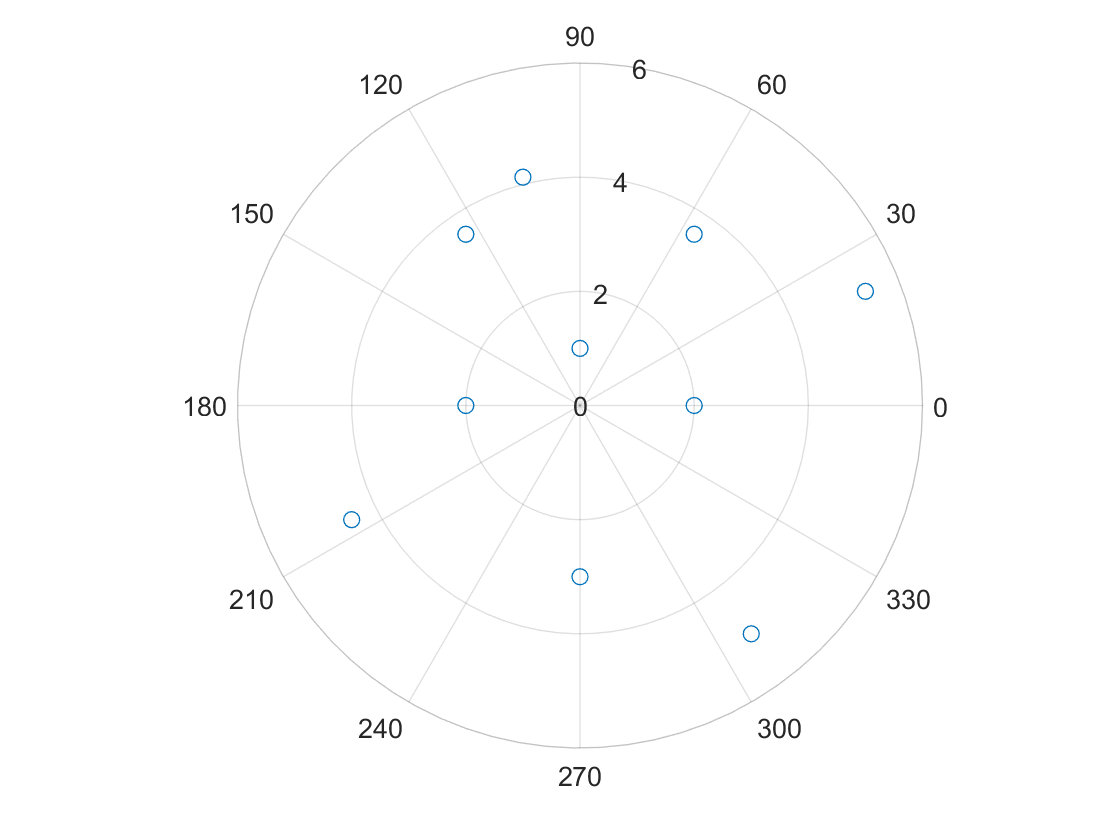

MarkerType = 'o';
Z = [2+3i 2 -1+4i 3-4i 5+2i -4-2i -2+3i -2 -3i 3i-2i];
polarplot(Z,...
    MarkerType)                              % Specify marker symbol

### Define Line Specifications

Create a polar plot and use the `LineSpec` option to specify a dashed green line with square markers. Use `Name,Value` pairs to specify the line width, point marker size, and point marker colors. Set the marker edge color to blue and set the marker face color using an RGB color value.

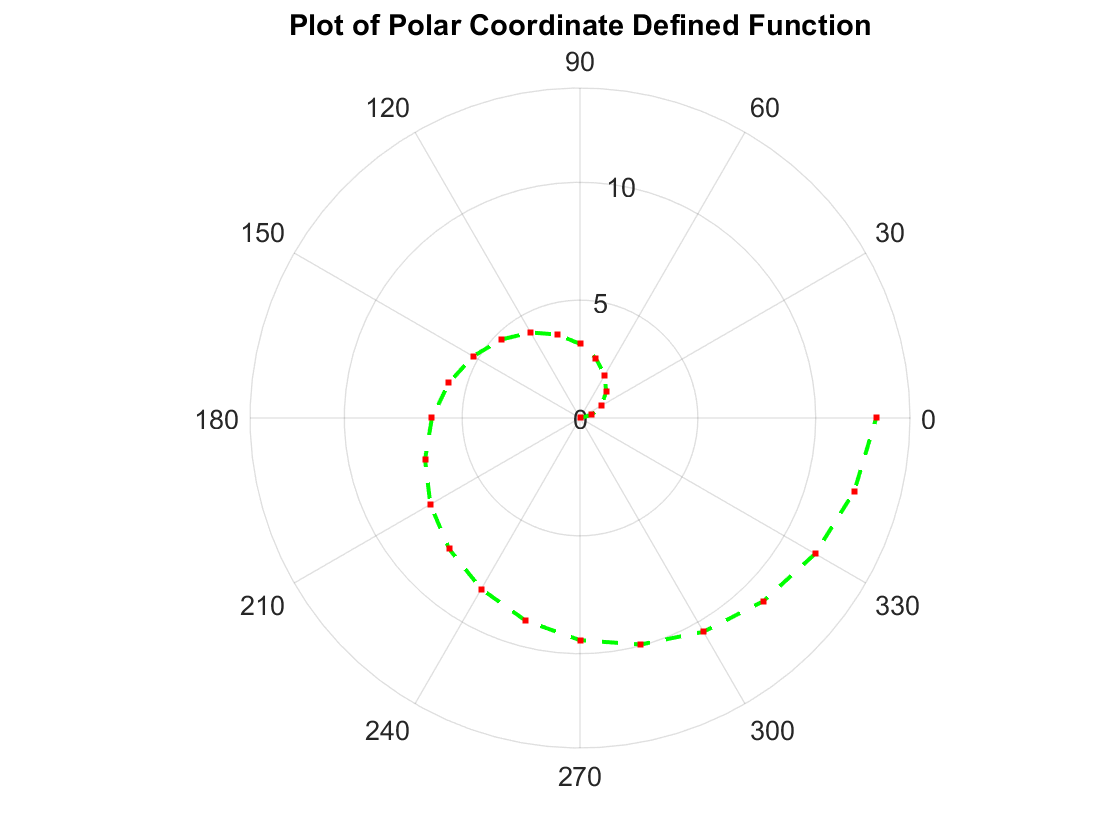

LineWidth = 1.5;
MarkerSize = 1.5;
MarkerEdgeColor = 'r';

theta = linspace(0,2*pi,25);
rho = 2*theta;
p = polarplot(theta,rho,'--gs',...              % Specify the line appearance
    "LineWidth",LineWidth,...                   % Set the line thickness  
    "MarkerSize",MarkerSize,...                 % Set the point size
    "MarkerEdgeColor",MarkerEdgeColor,...       % Set the point edge color
    "MarkerFaceColor",[0.5,0.5,0.5]);           % Set the fill point color

title("Plot of Polar Coordinate Defined Function")

## Additional Information

### Get All Polar Plot Properties

Graphics objects in MATLAB have many properties. To see all the properties of the polar plot, uncomment the following code

% get(p)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[polarplot](https://www.mathworks.com/help/matlab/ref/polarplot.html)